# Designing a Model using Ordinary Differential Equations (ODE) in MATLAB and Simulink

Kevin Chng

This example demostrates how to model ***"shell and tube heat exchanger" *** using ordinary differential equations. No control system is designed in this example, this is an open loop example.

However, if you are looking to design the shell and tube heat exchanger with control system, you may refers to my academia article:

[https://www.academia.edu/25122280/Modelling_Simulation_Control_of_Heat_Exchanger_by_Using_Matlab](https://www.academia.edu/25122280/Modelling_Simulation_Control_of_Heat_Exchanger_by_Using_Matlab)

## **Highlights : **

- How to model the ODE from your journal or textbook in MATLAB and Simulink

- Hint how to develop control system and GUI for your ODE model

## **Product Focus :**

- MATLAB

- Simulink

## Background : 

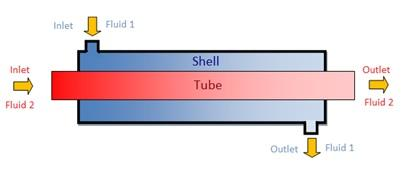

(Schematic Diagram of Shell and Tube Heat Exchanger)

A heat exchanger is a device designed to efficiently transfer or "exchange" heat from one matter to another. In this example, the cold fluild will flow through the shell to cold down the fluid flowing through the tube.

Here, we want to model the heat exchanger to monitor the temperature of outlet fluids. 

The ordinary differential equatios used to represent the changes of output temperature are shown as below:

Shell Side :


$$\frac{{\ dT}_s }{dt}=\left({\left(T_{s,inlet} -T_s \right)}-\ \frac{kA_i }{∆Z\rho_s F_s C_{p\ldotp s} }{\left(T_s -\ T_t \right)}-\frac{hA_{d\ } }{\rho_s F_s C_{p\ldotp s} }\left(T_s -\ T_{\infty } \right)\right)\left(\frac{\rho_s F_s }{\ m_{s\ \ } }\right)$$


Tube Side:


$$\frac{{dT}_t }{dt}=F_t {\left(T_{t,inlet} -T_t \right)}+\ \frac{kA_i }{∆Z\rho_t C_{p\ldotp t} }{\left(T_s -\ T_t \right)}\left(\frac{{\ \ \ \ \ \rho }_t \ \ \ \ }{m_t \ }\right)$$


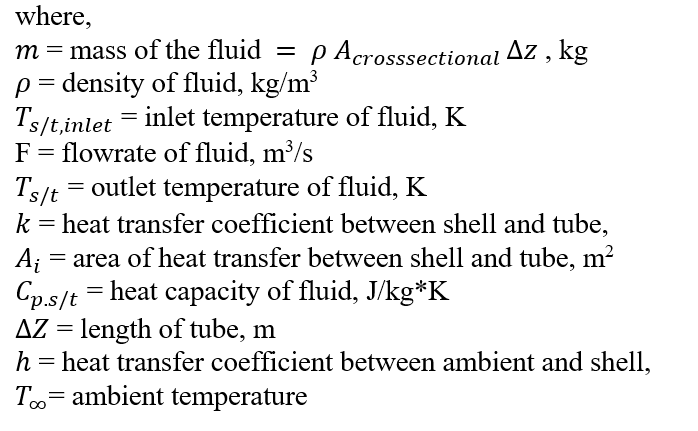

## 1.0 Define Initial Conditions

In the ODE equations, there are many unknown initial conditions. It requires domain knowledge to define the initial conditions

### 1.1 Heat Exchange Design Information

Ambient temperature (Celcius) $T_{\infty }$ :

T_ambient = 303.15;

Inner Diameter of Tube (m) :

Inner_diameter_tube = 0.1;

Outer Diameter of Tube (m) :

Outer_diameter_tube = 0.12;

Length of Tube (m) :

Length_tube = 1;

Number of Tube (m) :

Number_tube = 1;

Inner Diameter of Shell (m) :

Inner_diameter_shell = 0.2;

Outer Diameter of Shell (m) :

Outer_diameter_shell = 0.22;

Conductive Heat Transfer Coefficient for Tube-Shell (W/mK) $k$ :

Conductive_heattransfer_tube_shell = 40000;

Convective Heat Transfer Coefficient Shell-Ambient (W/m2K)  $h$:

convective_heattransfer_shell_ambient = 500;

Cross Sectional Area of Shell :

Cross_sectional_area_shell = 0.0254;

Cross Sectional Area of Tube :

Cross_sectional_area_tube = 0.0314;

Area of heat transfer between Shell and Tube :

At = 2*3.142*((Inner_diameter_tube+Outer_diameter_tube)/2)*Length_tube*Number_tube;

Area of heat transfer between Shell and Ambient :

Ad = 2*3.142*((Inner_diameter_shell+Outer_diameter_shell)/2)*Length_tube;

### 1.2 Fluid in Shell

Average Heat Capacity (J/kg*K) :

Average_heat_capacity_shell=4185;

Temperature Inlet (Celcius) :

Temperature_inlet_shell=300;

Density of Fluid (kg/m3) :

Density_fluid_shell = 1000;

Flow Rate of Fluid (m3/s)

Flow_rate_shell = 0.1;

Mass Flow Rate of Fluid in Shell

ms = Cross_sectional_area_shell*Density_fluid_shell*Length_tube;

### 1.3 Fluid in Tube

Average Heat Capacity (J/kg*K) :

Average_heat_capacity_tube=1200;

Temperature Inlet (Celcius) :

Temperature_inlet_tube=370;

Density of Fluid (kg/m3) :

Density_fluid_tube = 1030;

Flow Rate of Fluid (m3/s)

Flow_rate_tube = 0.2;

Mass Flow Rate of Fluid in Tube :

mt = Cross_sectional_area_tube*Density_fluid_tube*Length_tube;

## 2.0 Select Solver For ODE equation

Refers to [https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

This example will use 4 ODE Solvers :

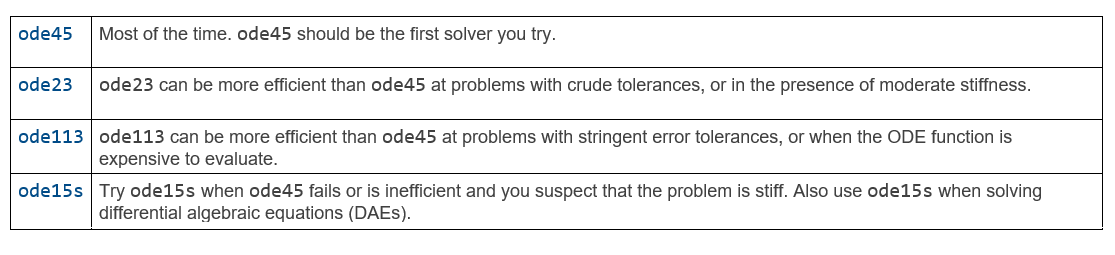

## 3.0 Code the ODE Equations in MATLAB

Assume the initial outlet temperature is equal to the inlet temperature for both shell and tube.

Temperature_shell(1)= Temperature_inlet_shell;
Temperature_tube(1) = Temperature_inlet_tube;

Code the ODE Equations in MATLAB


$$\frac{{\ dT}_s }{dt}=\left({\left(T_{s,inlet} -T_s \right)}-\ \frac{kA_i }{∆Z\rho_s F_s C_{p\ldotp s} }{\left(T_s -\ T_t \right)}-\frac{hA_{d\ } }{\rho_s F_s C_{p\ldotp s} }\left(T_s -\ T_{\infty } \right)\right)\left(\frac{\rho_s F_s }{\ m_{s\ \ } }\right)$$


dts_dt = ((Temperature_inlet_shell-Temperature_shell(1))...
    - (Conductive_heattransfer_tube_shell*At)*(Temperature_shell(1)-Temperature_tube(1))/(Length_tube*Density_fluid_shell*Flow_rate_shell*Average_heat_capacity_shell)...
    - (convective_heattransfer_shell_ambient*Ad)*(Temperature_inlet_shell-T_ambient)/(Density_fluid_shell*Flow_rate_shell*Average_heat_capacity_shell))...
    * (Density_fluid_shell*Flow_rate_shell/ms);


$$\frac{{dT}_t }{dt}=\left(F_t {\left(T_{t,inlet} -T_t \right)}+\ \frac{kA_i }{∆Z\rho_t C_{p\ldotp t} }{\left(T_s -\ T_t \right)}\right)\left(\frac{{\ \ \ \ \ \rho }_t \ \ \ \ }{m_t \ }\right)$$


dtt_dt = (Flow_rate_tube*(Temperature_inlet_tube-Temperature_tube(1))...
    + (Conductive_heattransfer_tube_shell*At)*(Temperature_shell(1)-Temperature_tube(1))/(Length_tube*Density_fluid_tube*Average_heat_capacity_tube))...
    * (Density_fluid_tube/mt);

## 4.0 Transform the ODE equations for ODE Solver

(1) Transform the 2 ODE equations to 

(2) Represent Temperature_shell(1) & Temperature_tube(1)  by y(1) and y(2)

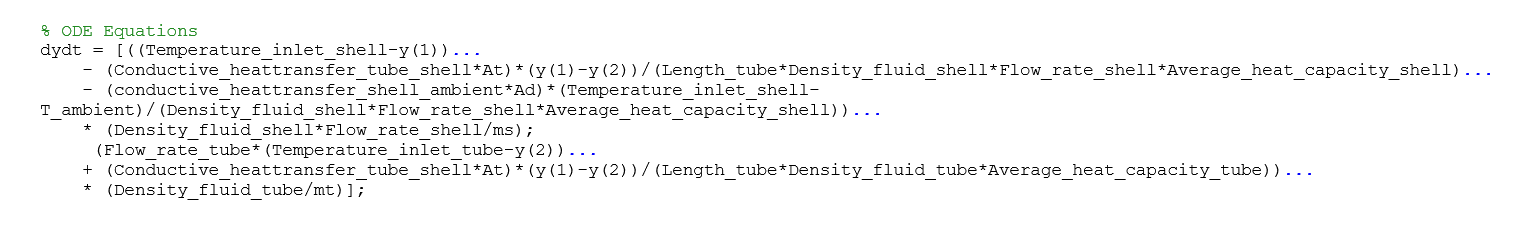

(3) Create a function to include initial conditions and ODE equations in (2)

*Do not include the initial condition for both outlet temperature (Our updating variables)

edit model_matlab.m

## 5.0 Run ODE Solver in MATLAB

ssume the initial outlet temperature is equal to the inlet temperature for both shell and tube.

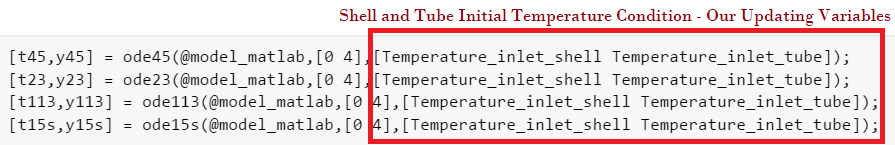

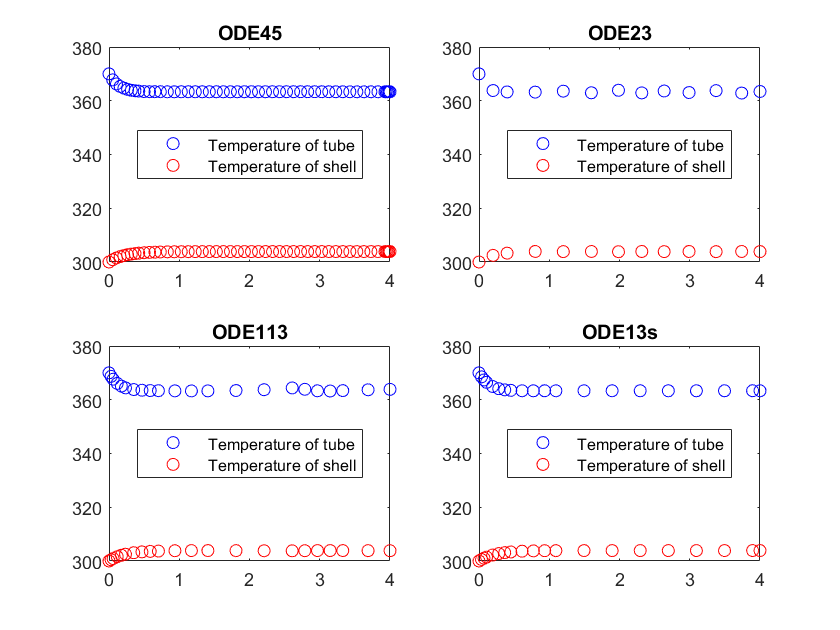

[t45,y45] = ode45(@model_matlab,[0 4],[Temperature_inlet_shell Temperature_inlet_tube]);
[t23,y23] = ode23(@model_matlab,[0 4],[Temperature_inlet_shell Temperature_inlet_tube]);
[t113,y113] = ode113(@model_matlab,[0 4],[Temperature_inlet_shell Temperature_inlet_tube]);
[t15s,y15s] = ode15s(@model_matlab,[0 4],[Temperature_inlet_shell Temperature_inlet_tube]);

figure();

subplot(2,2,1)
plot(t45,y45(:,2),'bo')
hold on
plot(t45,y45(:,1),'ro')
legend('Temperature of tube','Temperature of shell','location','best')
title('ODE45')

subplot(2,2,2)
plot(t23,y23(:,2),'bo')

hold on
plot(t23,y23(:,1),'ro')
legend('Temperature of tube','Temperature of shell','location','best')
title('ODE23')

subplot(2,2,3)
plot(t113,y113(:,2),'bo')
hold on
plot(t113,y113(:,1),'ro')
legend('Temperature of tube','Temperature of shell','location','best')
title('ODE113')

subplot(2,2,4)
plot(t15s,y15s(:,2),'bo')
hold on
plot(t15s,y15s(:,1),'ro')
legend('Temperature of tube','Temperature of shell','location','best')
title('ODE13s')

## 5.0 Design the Model in Simulink

I have built the simulink model :

open model_simulink.slx

1) You may develop your ODE in MATLAB block and Simulink Block. In my simulink, I develop Shell Side ODE in MATLAB block, but develop Tube Side ODE in Simulink Block.

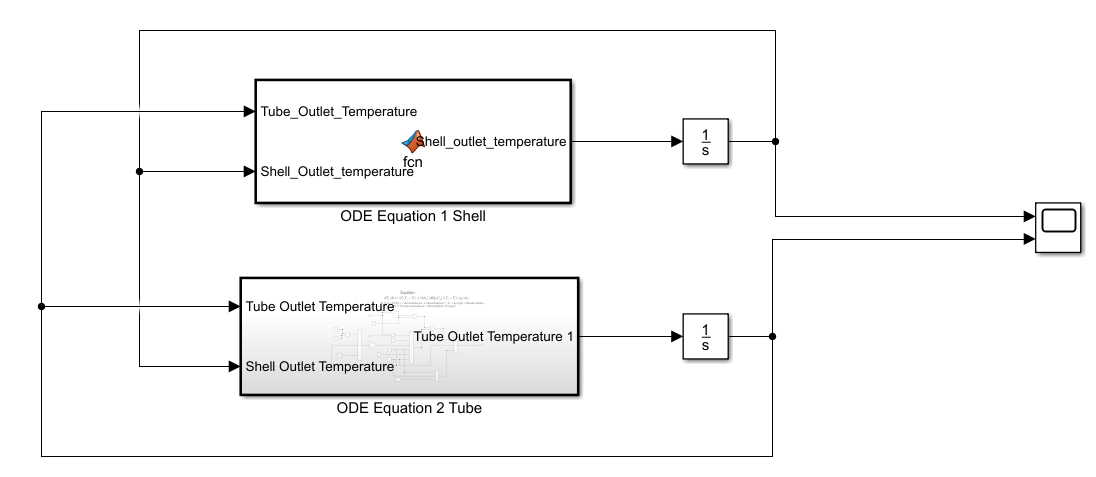

2) Shell Side ODE in MATLAB Block

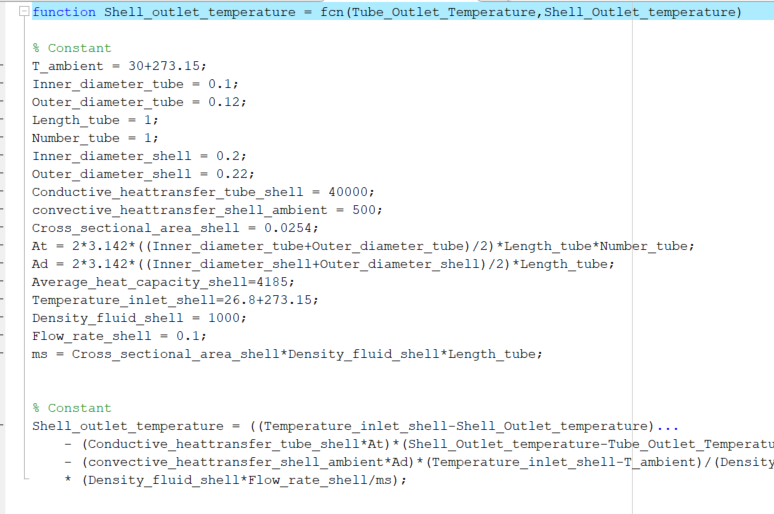

3) Tube Side ODE in Simulink Block

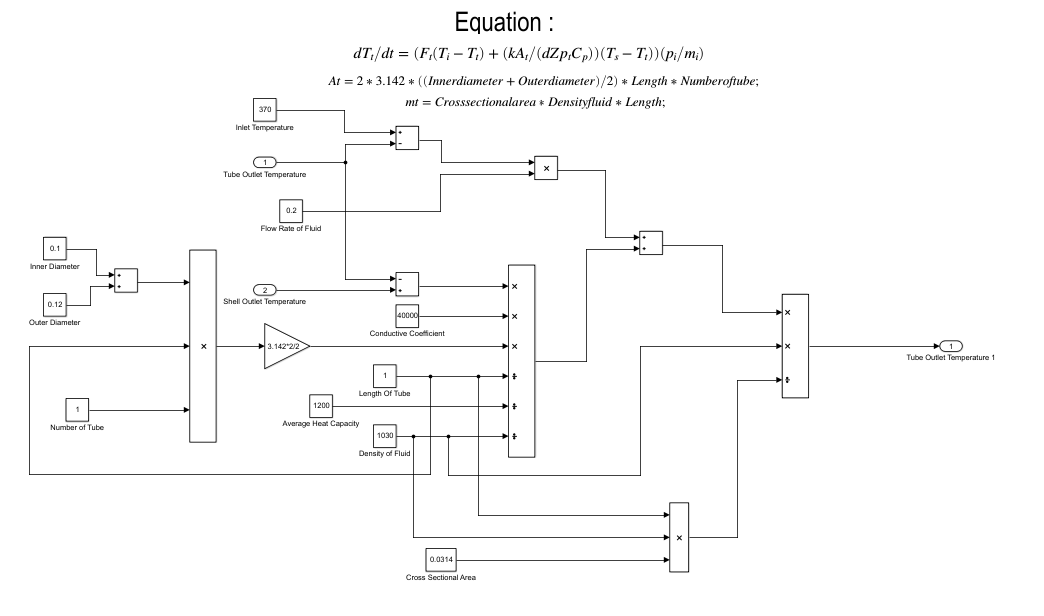

4) To get the output y(x), we have to integrate, because y(x) was expressed in terms of its derivative dy/dx

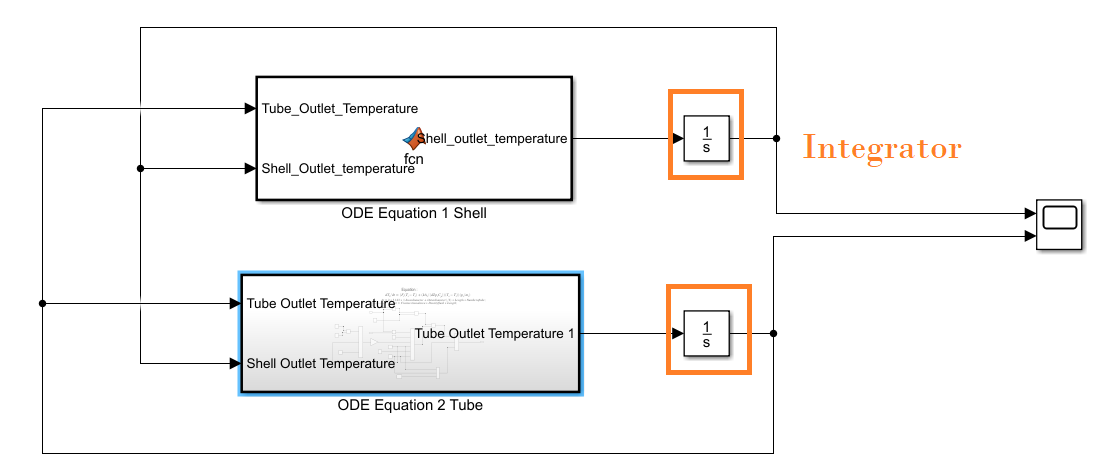

5) Set the initial value in the integrator y(0), 

for shell_out_temperature(0)=300,

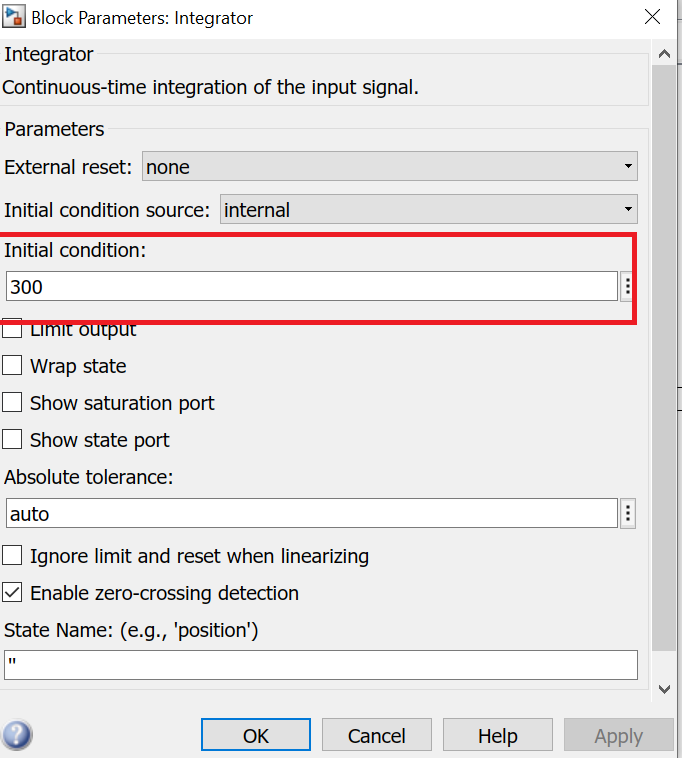

for tube_out_temperature(0)=370,

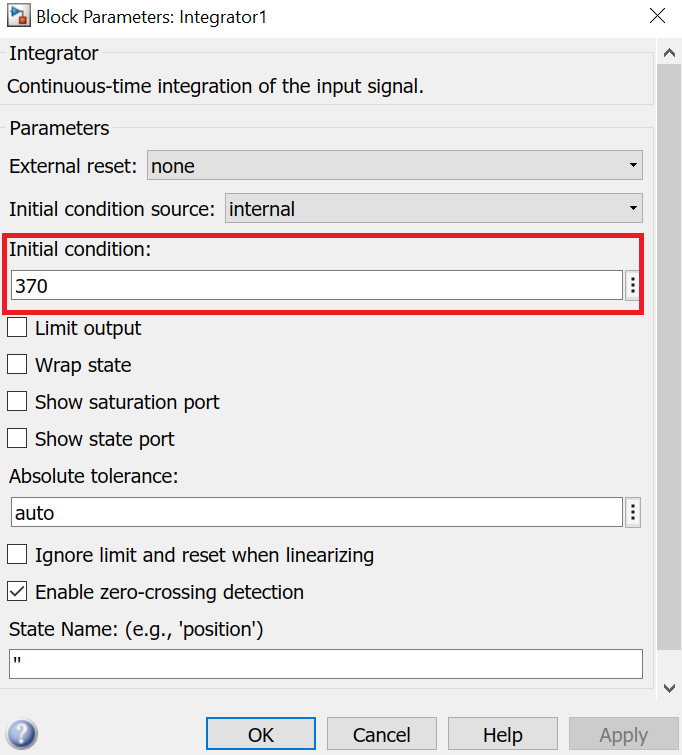

6) Select the ODE solver to run the simulation (Simulation(On top the tab)>Model Configuration Parameters)

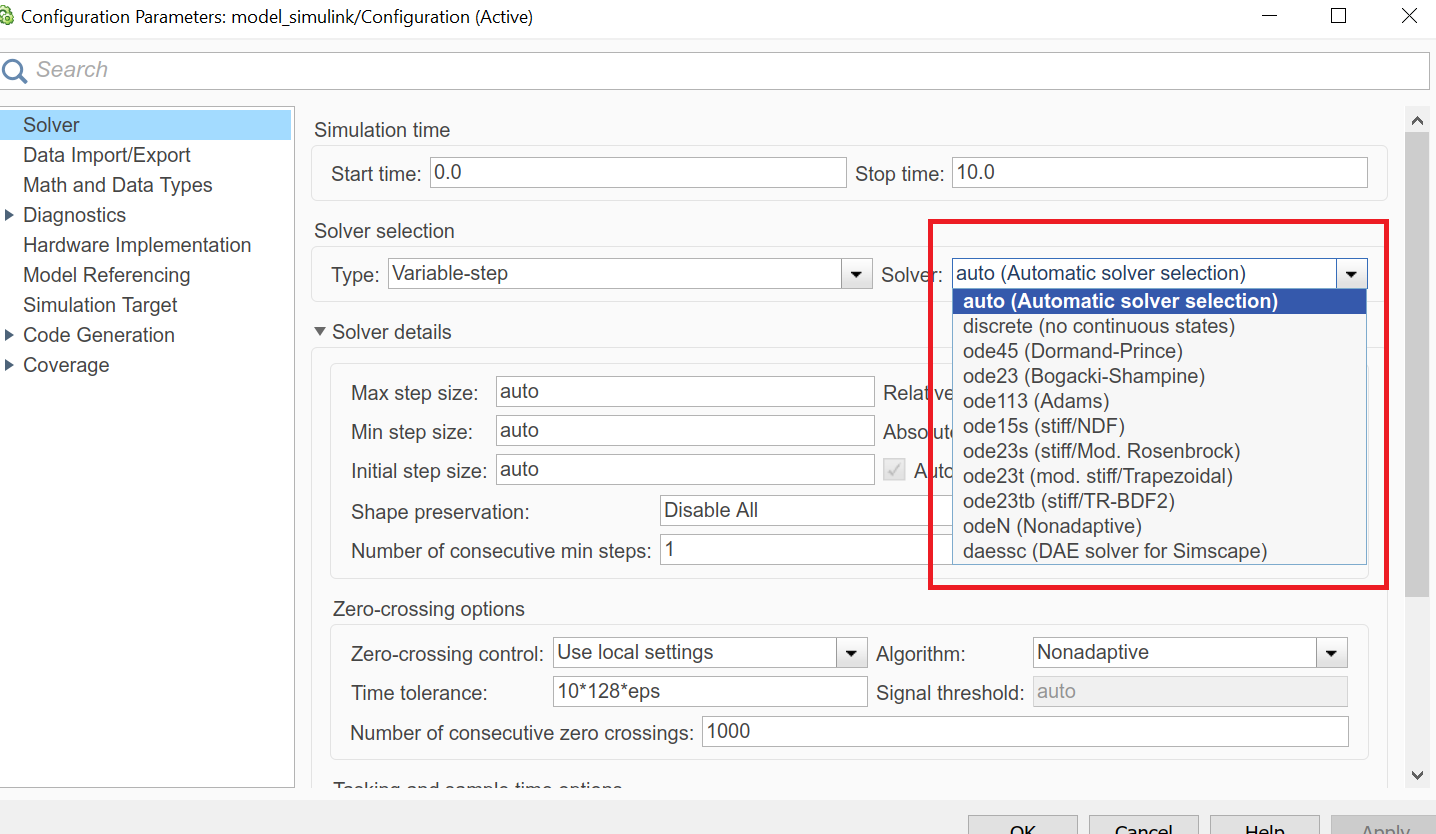

7) Run the Simution, and open the scope (Result is same as the model we developed in MATLAB)

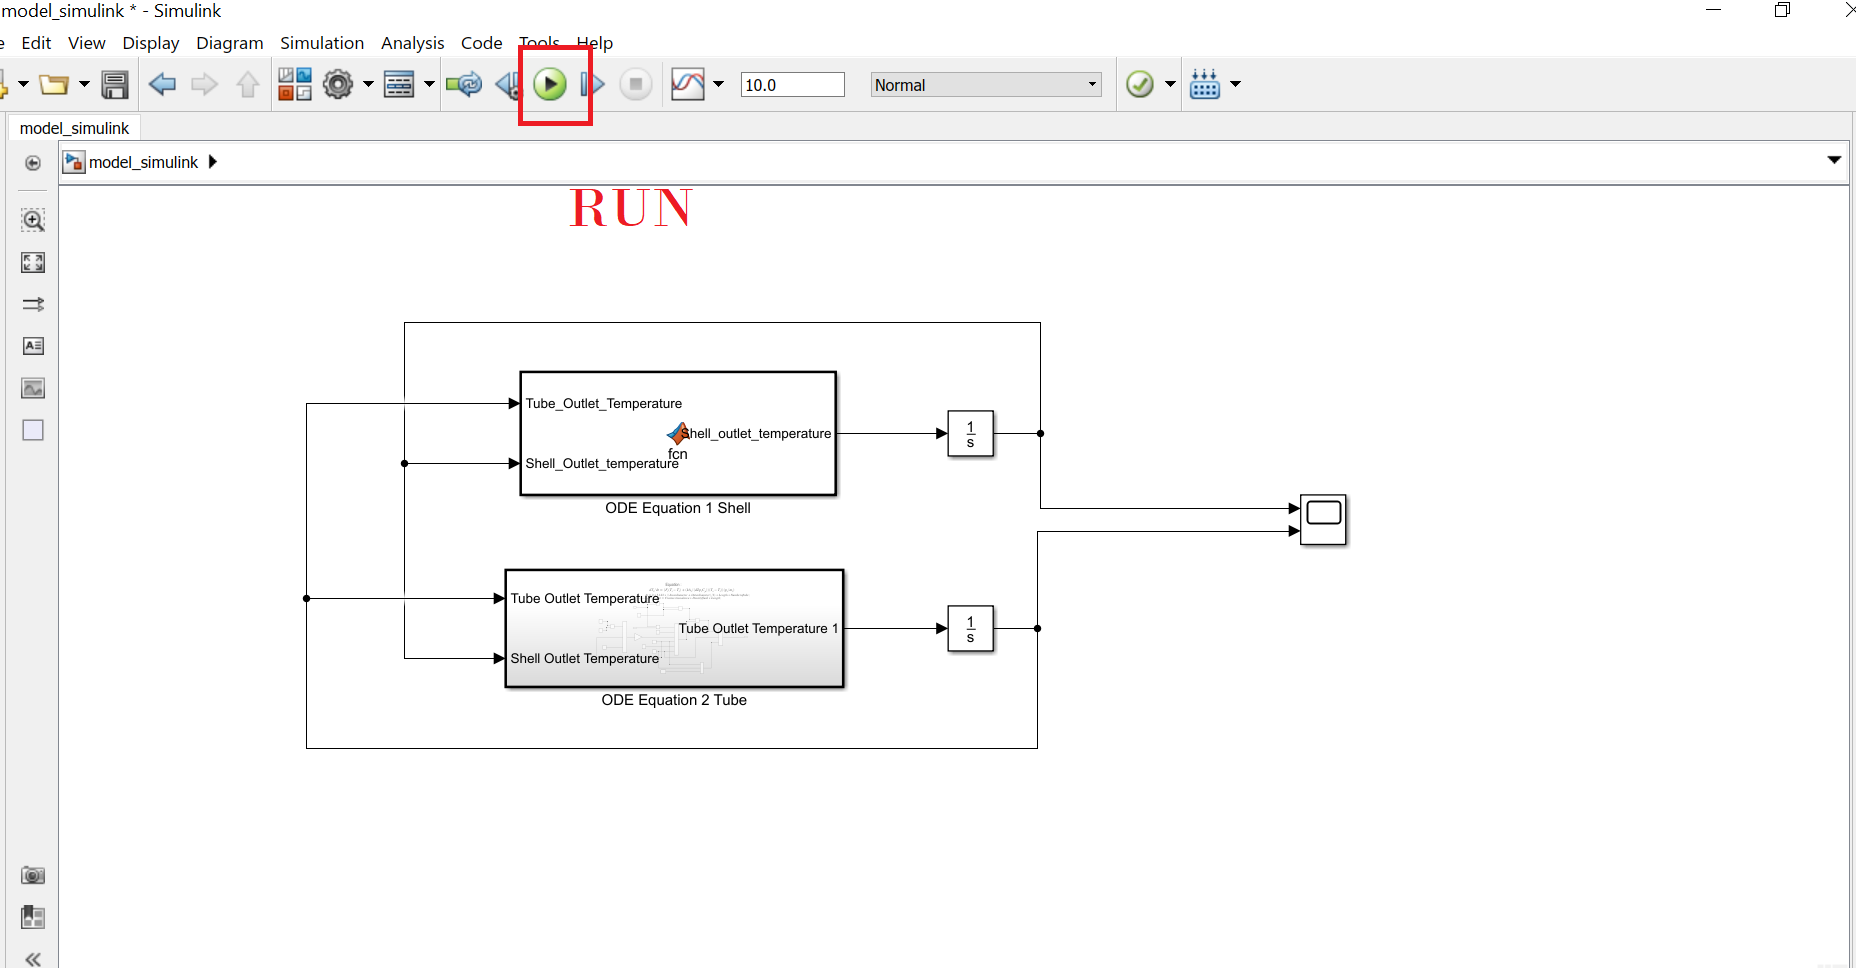

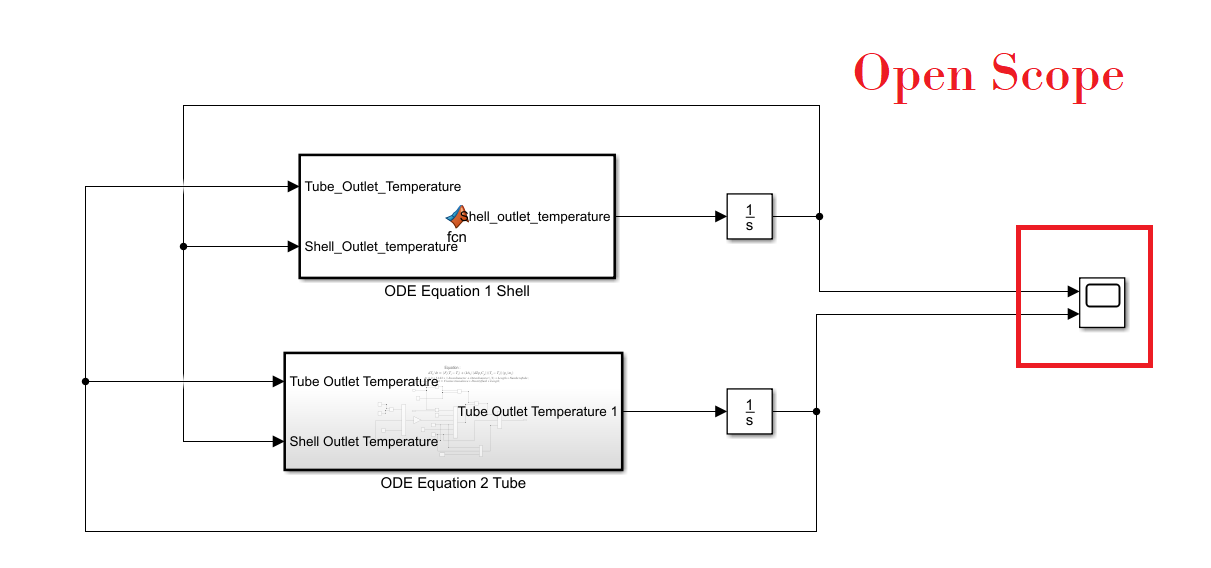

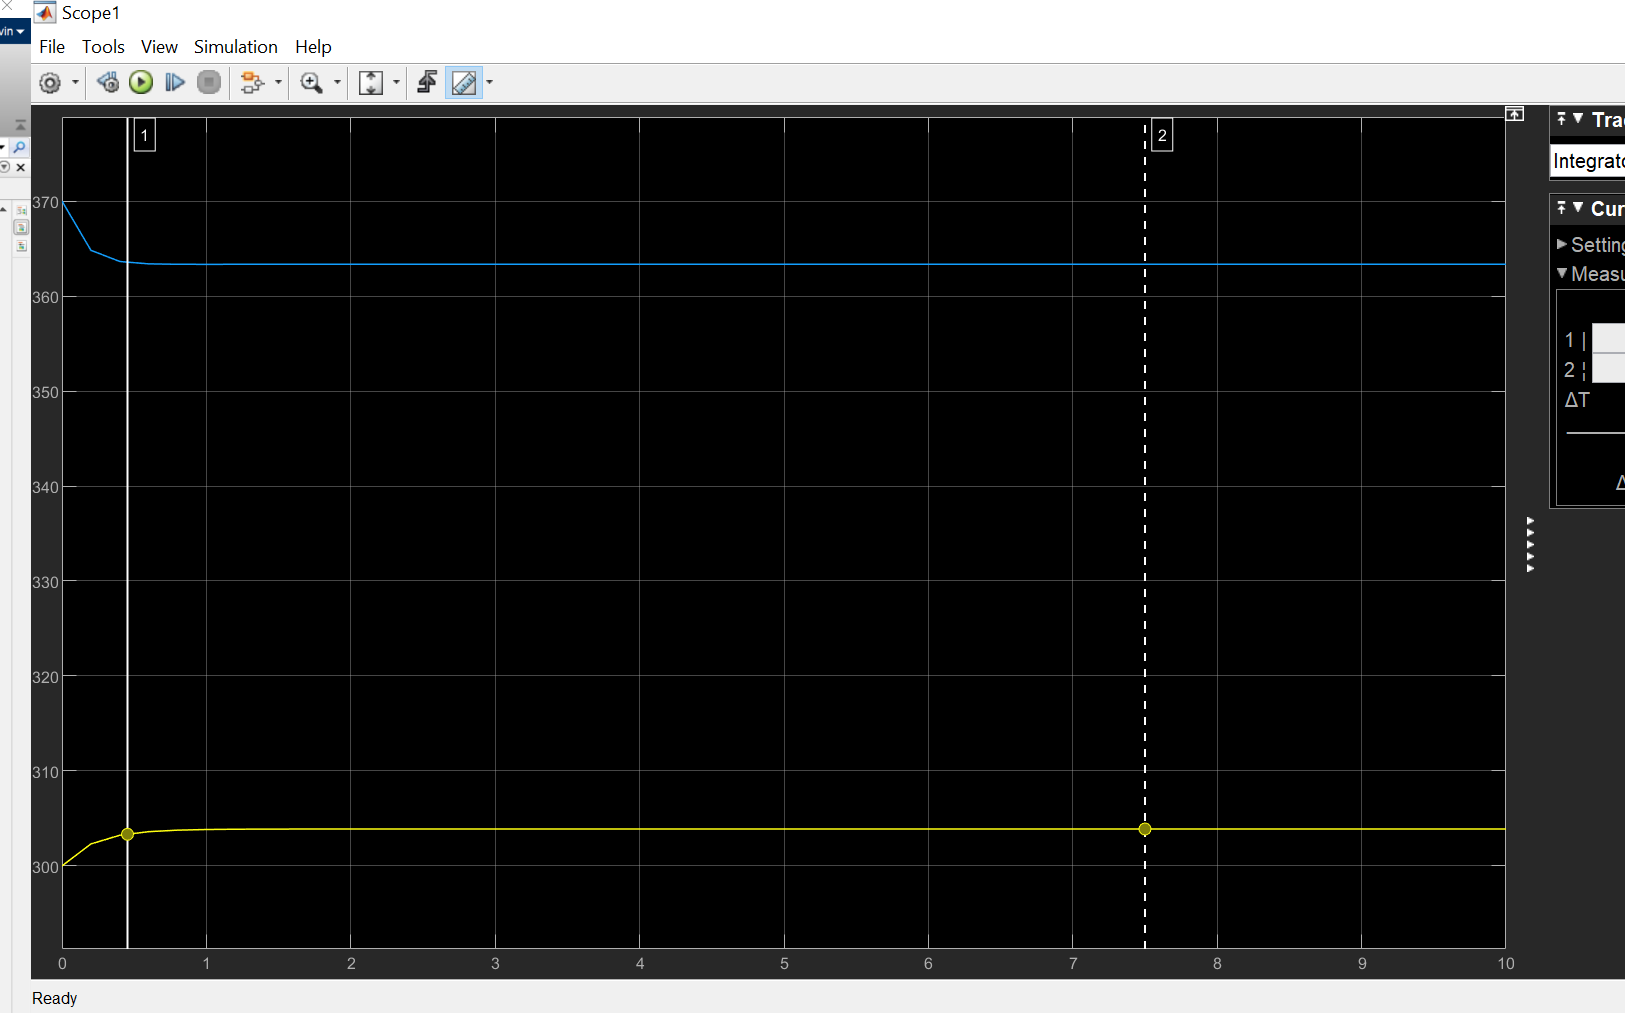

## 6.0 Further Development

1) You may consider to perform linearization of the Non-linear ODE equation (Laplace Transform the ODE to transfer function), since most of process control is developed based on linear equation. For detail, you may refer to [https://www.academia.edu/25122280/Modelling_Simulation_Control_of_Heat_Exchanger_by_Using_Matlab](https://www.academia.edu/25122280/Modelling_Simulation_Control_of_Heat_Exchanger_by_Using_Matlab)

2) You may considert to use [app designer](https://www.mathworks.com/products/matlab/app-designer.html) develope a front-end GUI to tune the parameter: (example : [https://www.mathworks.com/matlabcentral/fileexchange/68226-shell-tube-heat-exchanger-simulator)](https://www.mathworks.com/matlabcentral/fileexchange/68226-shell-tube-heat-exchanger-simulator))